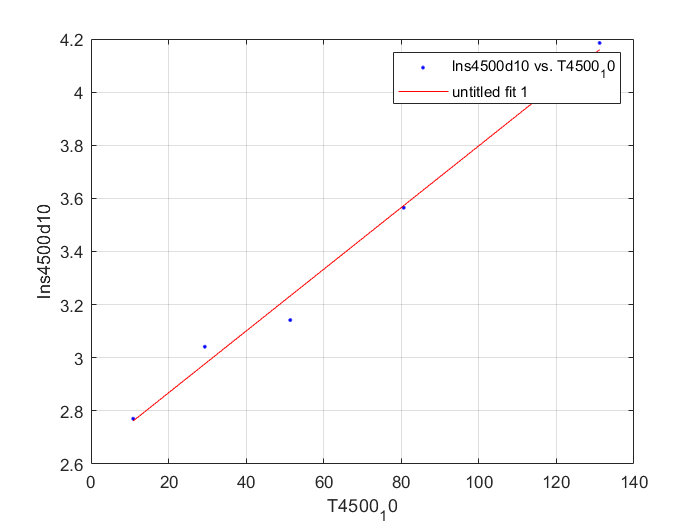

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( T4500_10, lns4500d10 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns4500d10 vs. T4500_10', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T4500_10
ylabel lns4500d10
grid on



%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01162  (0.009382, 0.01387)
  %     p2 =       2.636  (2.47, 2.801)

%Goodness of fit:
 % SSE: 0.01327
  %R-square: 0.9891
  %Adjusted R-square: 0.9855
  %RMSE: 0.0665